# openExample("predmaint/BatteryCyclingDataFeatureExtractionExample")Modeling and Optimizing a Battery Charging Profile

In this project, you will use MATLAB to model a battery charging profile. You will fit real lithium‑ion battery data in MATLAB, compute energy transfer through numerical integration, and analyze key performance characteristics such as charge‑rate behavior and efficiency losses.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Given data for a lithium-ion battery charging profile, use MATLAB to fit the equation for voltage provided in the Project Description.

- Plot the following curves: voltage vs. time, current vs. time, and power vs. time.

- Use integration to compute the total energy delivered to the battery (area under power-time curve).

- Analyze the rate of voltage change at different intervals (calculate derivatives), compute the time to reach 80% and 100% charge, and compute the energy lost due to resistance.

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Fit the voltage equation to a lithium-ion battery profile

Given real time-series voltage data for a lithium-ion battery, use MATLAB Curve Fitting Toolbox to fit the equation $V\left(t\right)=V_{\max } \left(1-e^{-\frac{t}{\mathrm{RC}}} \right)$ and model the battery charging profile as a simple RC-circuit analog.

Load MathWorks example lithium-ion batteries data by following the steps [here](https://www.mathworks.com/help/predmaint/ug/data-analysis-and-feature-extraction-for-battery-raw-cycling-data.html). The page also includes information about the dataset, how the data was recorded, and the battery's maximum voltage.

**Note**: The battery from this example dataset has been cycled to failure (charged and discharged repeatedly). For this project, you may choose to use data from a single cycle and focus only on the period of time within a cycle that the battery is being charged. The battery is fully charged at 3.6V. This example battery uses a dynamic fast charging profile, but for this project, you will attempt to model the charging profile using a simple exponential capacitor charging equation.

Then, follow the workflow outlined in the [documentation](https://www.mathworks.com/help/curvefit/fit.html) to fit the voltage equation to your selected data. Plot the data and fitted curve in the same figure and, finally, print the goodness-of-fit statistics.

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.

% STEP 1
% Load the example battery dataset

dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile)
load("singleCellLifeTimeData.mat")
head(data, 5)

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________    ___________

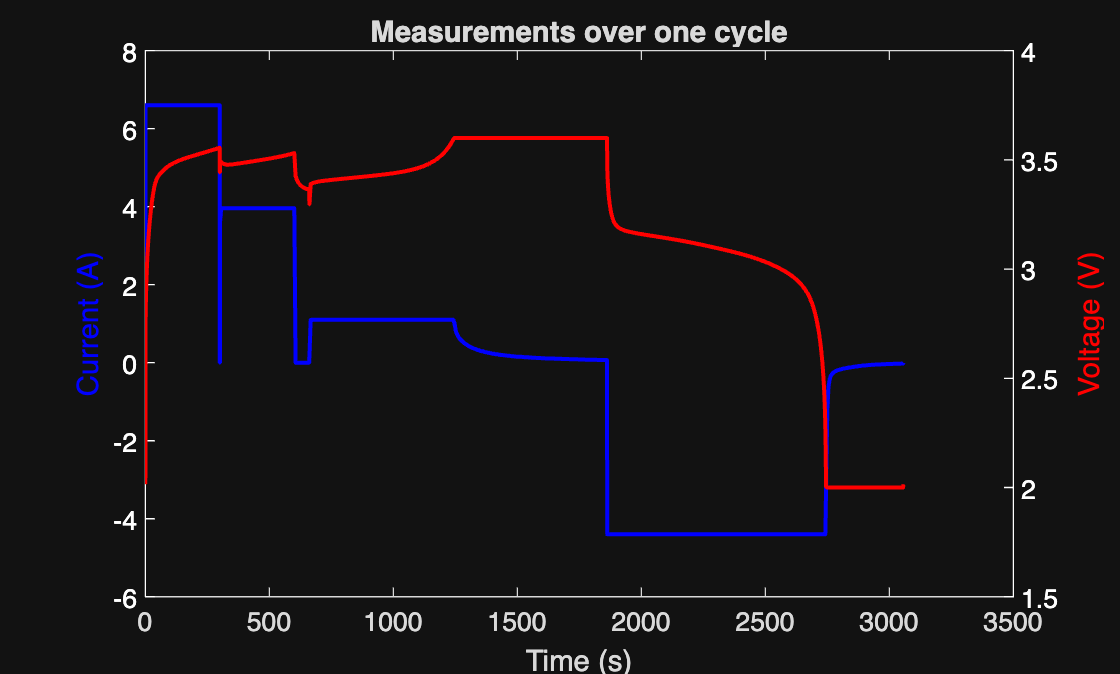


% STEP 2
% Pre-process the data to focus on a single cycle, and the period of time
% within that cycle that the battery was being charged

cycleData = data(data.Cycle_Index == 1, :); % cycle 1
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));
figure;

% extract & define voltage/current data 
voltageData = cycleData.Voltage;
currentData = cycleData.Current;

% plot current data (blue)
yyaxis left;
ax = gca;
ax.YAxis(1).Color = 'white';
plot(cycleData.DateTime,currentData, '-b', 'LineWidth', 1.5);
ylabel('Current (A)', 'Color', 'blue');

% plot voltage data (red)
yyaxis right;
ax = gca;
ax.YAxis(2).Color = 'white';
plot(cycleData.DateTime,voltageData, '-r', 'LineWidth', 1.5);
ylabel('Voltage (V)', 'Color', 'red');
xlabel("Time (s)");
title('Measurements over one cycle');

% STEP 3
% Follow the provided workflow to fit the voltage equation to your selected
% data. 
% Hint: Vmax is known, so the only unknown in the equation is RC (also
% known as tau, the RC time constant - it is equivalent to the time it takes
% for a capacitor to reach ~63.2% of its max voltage). When you are fitting
% the curve to the data, you are essentially estimating the unknown
% parameter, tau.

% Define the voltage equation parameters
t = cycleData.DateTime; 
charging = currentData > 0; % show voltage for when battery is charging
vCharge = voltageData(charging); % charging voltage data only
vMin = vCharge(1) % Vmin != 0

vMin = 2.0326

vMax = max(vCharge) % Maximum voltage

vMax = 3.6004

tCharge = t(charging); % charging time period only
vTau_thy = vMin + .632*(vMax-vMin) % voltage when t = tau

vTau_thy = 3.0235

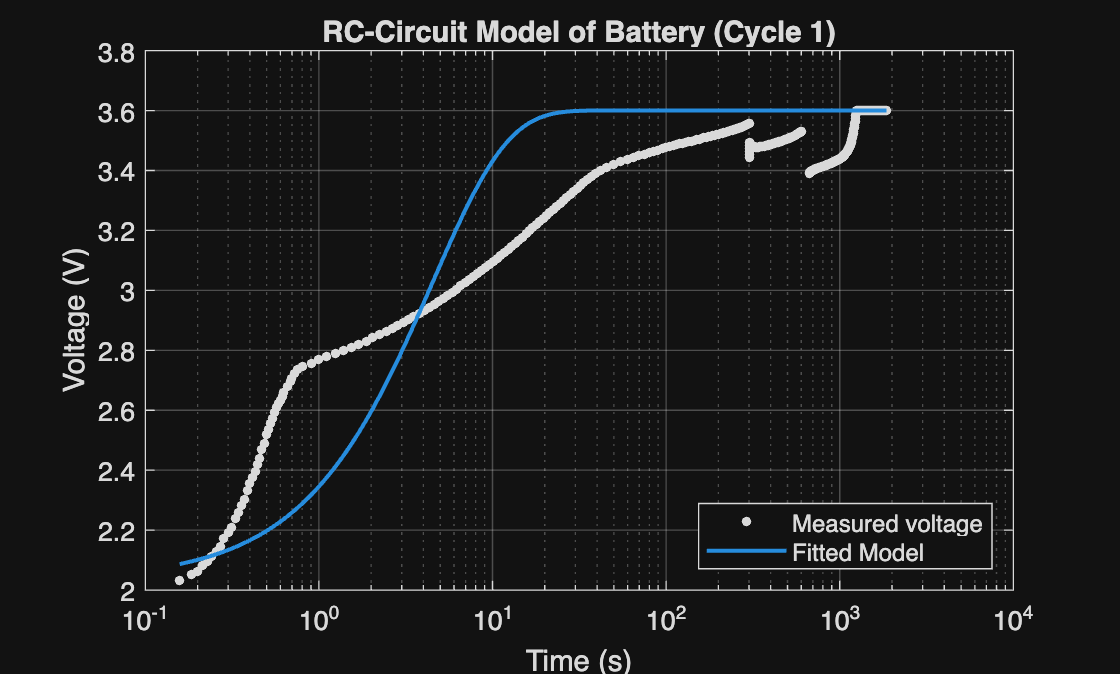


% Find the index where voltage is closest to vTau
tauIndex = find(vCharge >= vTau_thy,1, 'first');
tau = tCharge(tauIndex); % tau index
vTau_exp = vCharge(tauIndex); % voltage at tau
% STEP 4
% Plot the data and the fitted curve in the same figure.


ft = fittype('vMin + (vMax-vMin)*(1 - exp(-t/tau))', ... % create fittype for fitting
    'independent', 't', 'dependent', 'V', ... $ indep var = t, depen var = V
    'coefficients', {'tau'}, ... 
    'problem', {'vMax','vMin'}); % Define vmax as problem parameter 

[result, gof] = fit(tCharge, vCharge, ft, ...
    'StartPoint', tau, 'Lower', 0, 'problem', {vMax, vMin});

figure;
h = plot(result, tCharge, vCharge);
set(gca, 'XScale', 'log')
xlabel('Time (s)');
ylabel('Voltage (V)');
title('RC-Circuit Model of Battery (Cycle 1)');
legend('Measured voltage', 'Fitted Model', 'Location', 'southeast');
grid on;


% Display the goodness-of-fit statistics.
disp(gof)

           sse: 14.8641
       rsquare: 0.7490
           dfe: 611
    adjrsquare: 0.7490
          rmse: 0.1560



## Task 2: Plot the electrical terms that express how energy moves in a circuit

To visualize the battery's charging policy, write code to visualize the current, voltage, and power measurements for one charging cycle. Present the visualization as one figure with three subplots, one each for:

- Voltage vs. time

- Current vs. time

- Power vs. time

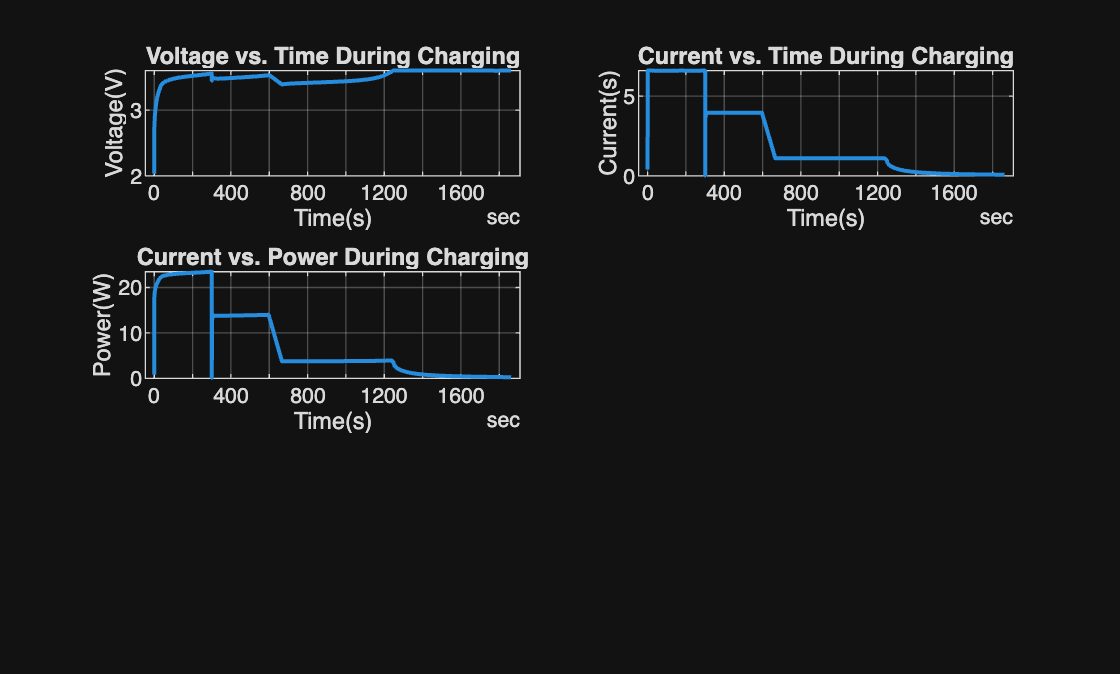

% Insert your code in the spaces below (or make use of helper functions and
% indicate where they can be found). Ensure your code is well-documented.

%Filter the current, voltage, and time measurements to only the charging
%portion

chargingMask = currentData > 0; %Create logical mask to idenitfy measurements with positive current

chargingTime = seconds(t(chargingMask)); %Ensures that only the positive times are included
chargingTime = chargingTime - chargingTime(1); %Causes graph to begin at 0 secs

%Extract charging voltage and current to then calculate charging power
chargingVoltage = voltageData(chargingMask);
chargingCurrent = currentData(chargingMask);
chargingPower = chargingVoltage .* chargingCurrent;


% STEP 1
% Create a figure handle and initialize the first subplot. Plot voltage vs.
% time.

figure;

subplot(3, 2, 1); %Divides figure into 3 rows 2 columns at the top of the graph (position 1)
plot(chargingTime, chargingVoltage, 'LineWidth', 1.5); %Plots voltage vs. time
xlabel('Time(s)');
ylabel('Voltage(V)');
title('Voltage vs. Time During Charging');

grid on;

% STEP 2
% Use a second subplot to plot current vs. time.

subplot(3,2,2); %Uses middle position of figure
plot(chargingTime, chargingCurrent, 'LineWidth', 1.5);
xlabel('Time(s)');
ylabel('Current(s)');
title('Current vs. Time During Charging');

grid on;

% STEP 3
% Use a third subplot to plot power vs time.
% Hint: P = I * V where I is current in amps. You will first
% need to compute power before you can create this plot.

subplot(3, 2, 3); %Uses bottom position of figure
plot(chargingTime, chargingPower, 'LineWidth', 1.5);
xlabel('Time(s)');
ylabel('Power(W)');
title('Current vs. Power During Charging');

grid on;

## Task 3: Compute analytical results

To get started on using MATLAB for numerical integration and differentiation, start with this [doc page](https://www.mathworks.com/help/matlab/numerical-integration-and-differentiation.html?s_tid=CRUX_lftnav).

- Conduct a rate-of-change analysis by computing the derivative at key intervals in the voltage data

- Compute the time required to reach 80% and 100% charge

- Compute the total energy delivered to the battery by using integration to calculate the area under the power-time curve.

- Estimate the resistive energy loss

- Save the results to a summary table.

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.

% STEP 1: Compute the rate of voltage change at different key time
% intervals. This helps you mathematically characterize the battery's
% charging profile and is more reliable than simply eyeballing the voltage
% vs. time plot. 
% Optional: plot the points of notable transitions in charging dynamics in
% the voltage vs. time plot generated above
% Hint: explore using the gradient function

voltageGradient = gradient(vCharge, tCharge); % tracks dV/dt
keyIndices = [1, round(tauIndex), round(2*tauIndex), round(3*tauIndex), round(4*tauIndex), round(5*tauIndex), round(6*tauIndex), round(7*tauIndex), round(8*tauIndex), round(9*tauIndex)]; % key indices are in terms of tau 
% for loop to output dV/dt at key indices

for i = keyIndices
    fprintf('t = %6.1f s | dV/dt = %.5f V/s\n', tCharge(i), voltageGradient(i));
end

t =    0.2 s | dV/dt = 0.70662 V/s
t =    7.0 s | dV/dt = 0.02602 V/s
t =  124.7 s | dV/dt = 0.00051 V/s
t =  351.2 s | dV/dt = 0.00011 V/s
t =  591.6 s | dV/dt = 0.00032 V/s
t =  901.7 s | dV/dt = 0.00013 V/s
t = 1131.7 s | dV/dt = 0.00048 V/s
t = 1366.7 s | dV/dt = -0.00002 V/s
t = 1616.7 s | dV/dt = -0.00000 V/s
t = 1861.7 s | dV/dt = 0.00016 V/s


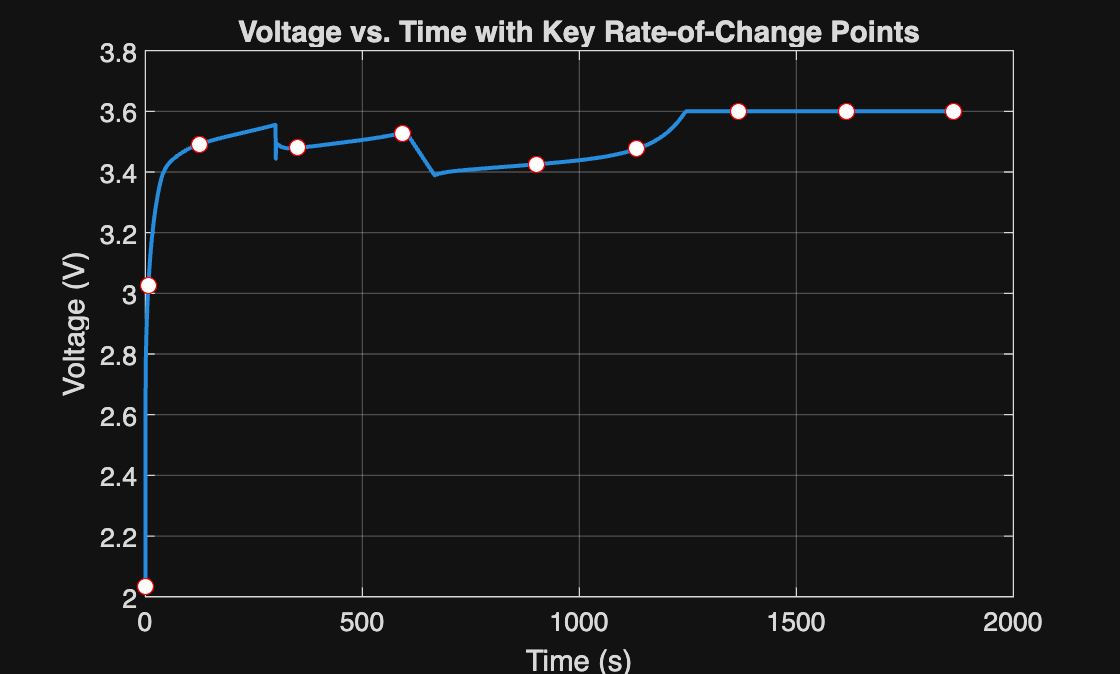

figure;
plot(tCharge, vCharge, 'LineWidth', 1.5); 
hold on;
plot(tCharge(keyIndices), vCharge(keyIndices), 'ro', 'MarkerFaceColor', 'w');
xlabel('Time (s)'); ylabel('Voltage (V)');
title('Voltage vs. Time with Key Rate-of-Change Points');
grid on;


% STEP 2: Compute the time required to reach 80% charge and 100% charge

voltage80 = vMin + .8*(vMax-vMin);

index80 = find(vCharge >= voltage80, 1, 'first');
index100 = find(vCharge >= vMax, 1, 'first');

fprintf('\nTime to reach 80%% charge (%.3f V): %.1f s\n', voltage80, tCharge(index80));


Time to reach 80% charge (3.287 V): 24.5 s


fprintf('\nTime to reach 100%% charge (%.3f V): %.1f s\n', vMax, tCharge(index100));


Time to reach 100% charge (3.600 V): 1246.7 s


% STEP 3: Use integration to calculate the area under the power-time curve.
% This represents the total energy delivered to the battery during charging.
% Hint: explore using the trapz function
totalEnergy = trapz(tCharge, chargingPower);
% STEP 4: Estimate the resistive energy loss. 
% Hint: use Joule's heating formula (P = I^2 * R) to estimate power loss in
% watts. The energy loss is given as E = P * t, where t is time in seconds
% and energy is in joules.
resistance = mean(cycleData.Internal_Resistance);
powerLoss = chargingCurrent.^2 * resistance;  % power loss in watts
energyLoss = trapz(tCharge, powerLoss);

% STEP 5: Save results to a summary table. Display the table.



## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning (for example, why would engineers want to compute the analytical results in Task 3?):

What are some limitations of your work?

What are practical next steps?